# Program Description

run('master_setting_sheet.mlx');

## Program Instructions

## # of Laps and Tourque Division Cases

t_div = linspace(2, 3, 25);          %Vector of torque division values
end_runs = linspace(2, 25, 25);      %Vector of # of endurance laps run

## Sun-Planetary System

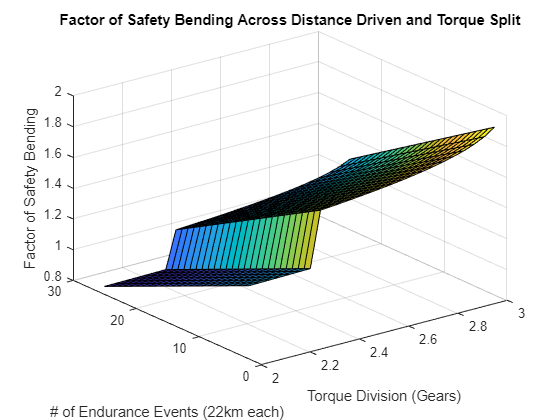

J_s = .34;                          %Geometry Factor
fos_bend_val = zeros(length(t_div), length(end_runs));
fos_wear_val = zeros(length(t_div), length(end_runs));

for i = 1:length(t_div) %Fills our FOS values for fB_s, fH_s
    for j = 1:length(end_runs)
        [fos_bend_val(i, j), fos_wear_val(i,j)] = GearStress_Sun(25.4*10^-3/sun.module, sun.teethNum, planet.sunStage.teethNum, J_s, t_div(i), end_runs(j));
    end
end

%Creates graphs for output

figure
surf(flip(t_div), flip(end_runs), fos_bend_val);
grid on
xlabel('Torque Division (Gears)')
ylabel('# of Endurance Events (22km each)')
zlabel('Factor of Safety Bending')
title('Factor of Safety Bending Across Distance Driven and Torque Split')

view([-37.50 30.00])

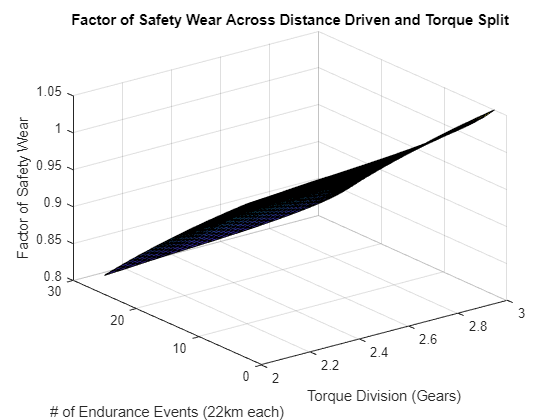

figure
surf(flip(t_div), flip(end_runs), fos_wear_val);
grid on
xlabel('Torque Division (Gears)')
ylabel('# of Endurance Events (22km each)')
zlabel('Factor of Safety Wear')
title('Factor of Safety Wear Across Distance Driven and Torque Split')

## Planet-Ring System

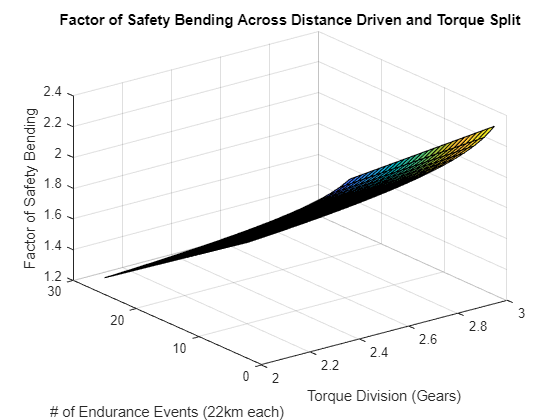

J_s = .40;                          %Geometry Factor
fos_bend_val = zeros(length(t_div), length(end_runs));
fos_wear_val = zeros(length(t_div), length(end_runs));

for i = 1:length(t_div) %Fills our FOS values for fB_s, fH_s
    for j = 1:length(end_runs)
        [fos_bend_val(i, j), fos_wear_val(i,j)] = GearStress_Ring(25.4*10^-3/ring.module, planet.ringStage.teethNum, ring.teethNum, J_s, t_div(i), end_runs(j));
    end
end

%Creates graphs for output

figure
surf(flip(t_div), flip(end_runs), fos_bend_val);
grid on
xlabel('Torque Division (Gears)')
ylabel('# of Endurance Events (22km each)')
zlabel('Factor of Safety Bending')
title('Factor of Safety Bending Across Distance Driven and Torque Split')

view([-37.50 30.00])

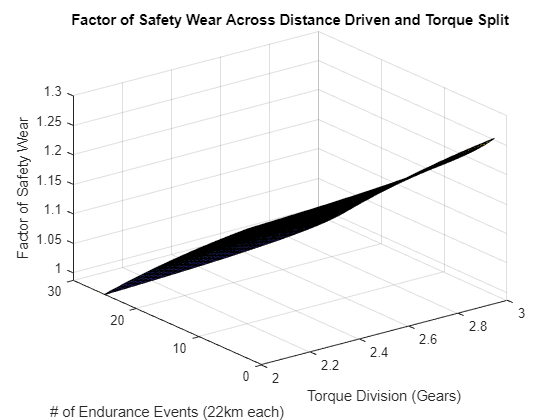

figure
surf(flip(t_div), flip(end_runs), fos_wear_val);
grid on
xlabel('Torque Division (Gears)')
ylabel('# of Endurance Events (22km each)')
zlabel('Factor of Safety Wear')
title('Factor of Safety Wear Across Distance Driven and Torque Split')